**Exercise 6.3**

Render the B´ezier patch and its control net

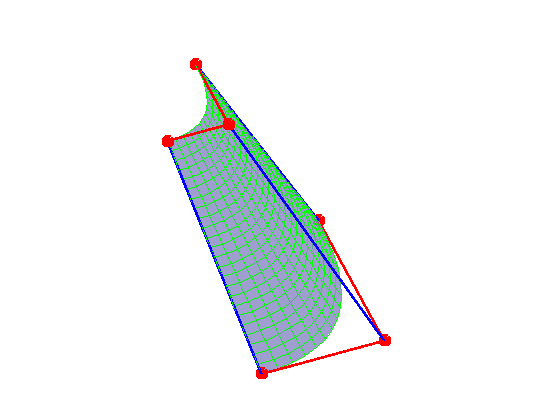

hold on 
clear all; 
%close all;
figure(1)
% Control poits for a degree 2 * 1 patch
P1 = [0 -4 0; 1 -4 0; 2 0 0;
    0 -2 2; 0.5 -2 2; 1 0 2;];
 nr = 2;
 nc = 3;
 
% surface evaluation
u = 1/2.; v = 1/2.;
tQ = deCasteljauSurf(P1,nr, nc, u, v);


%number of sampled points
snr = 25; % number of sampled points in row (in u direction)
snc = 15; % number of sampled points in col (in v direction)
%hold on;
Q1 = bezierSurf(P1, nr, nc, snr, snc);
%plot the surface
bezierSurfPlot(P1, Q1, nr, nc, snr, snc);
view(3)

axis off;